# Quantum Antibunching 2 Photon

Simulations for invited paper: C**omputational imaging with joint quantum and classical information**

#### First load data

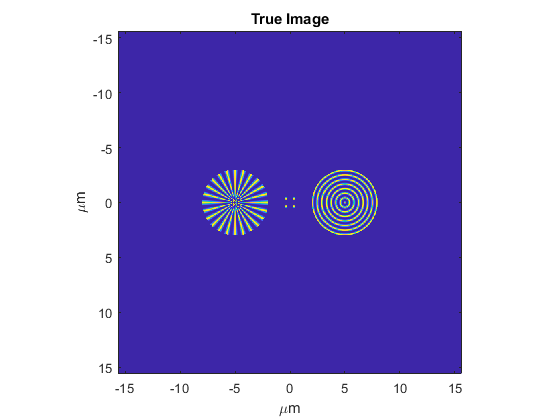

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SDI\MPSFIFforSDI")
x=load('xspatvecXT.mat');
x=x.Expression1;
fx=load('xspatfreqXT.mat');
fx=fx.Expression1;
y=load('yspatvecXT.mat');
y=y.Expression1;
fy=load('yspatfreqXT.mat');
fy=fy.Expression1;
trueimage=load("trueimageXT.mat");
trueimage=trueimage.Expression1;
figure; imagesc(x,y,trueimage)
xlabel('\mum')
ylabel('\mum')
axis square
title('True Image')

Noise Free

%1
for jj=1:4
    s=load(strcat('imgNFXT1',num2str(jj),'.mat'));
    imgNFXT12p(:,:,jj)=s.Expression1;
end 
%2
for jj=1:8
    s=load(strcat('imgNFXT2',num2str(jj),'.mat'));
    imgNFXT22p(:,:,jj)=s.Expression1;
end 
% %3
% for jj=1:6
%     s=load(strcat('imgNFXT3',num2str(jj),'.mat'));
%     imgNFXT3(:,:,jj)=s.Expression1;
% end 

Need to transform back into real space!!!

for jj=1:4
imgNFXT12p(:,:,jj)=real(ifftshift(ifft2((ifftshift(imgNFXT12p(:,:,jj))))));
end

for jj=1:8
imgNFXT22p(:,:,jj)=real(ifftshift(ifft2((ifftshift(imgNFXT22p(:,:,jj))))));
end


With Noise

%1
for jj=1:4
    s=load(strcat('imgNoiseXT1',num2str(jj),'.mat'));
    imgNoiseXT12p(:,:,jj)=s.Expression1;
end 
%2
for jj=1:8
    s=load(strcat('imgNoiseXT2',num2str(jj),'.mat'));
    imgNoiseXT22p(:,:,jj)=s.Expression1;
end 


Load in OTFs

%1
for jj=1:4
    s=load(strcat('OTFXT1',num2str(jj),'.mat'));
    OTFXT12p(:,:,jj)=s.Expression1;
end 
%2
for jj=1:8
    s=load(strcat('OTFXT2',num2str(jj),'.mat'));
    OTFXT22p(:,:,jj)=s.Expression1;
end 


## Plots no noise

figure;
t=tiledlayout(2,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


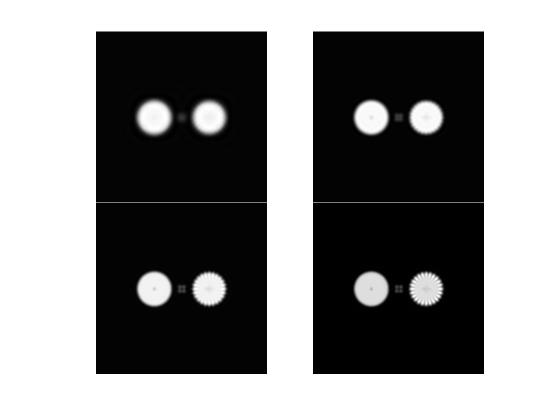

colormap gray
nexttile
imagesc(imgNFXT12p(:,:,1))
axis square
axis off
nexttile
imagesc(imgNFXT12p(:,:,2))
axis square
axis off
nexttile
imagesc(imgNFXT12p(:,:,3))
axis square
axis off
nexttile
imagesc(imgNFXT12p(:,:,4))
axis square
axis off

t.TileSpacing = 'none';


t=tiledlayout(2,4)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 4]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


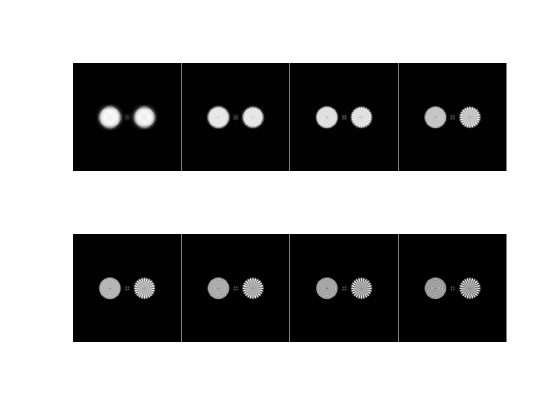

colormap gray
nexttile
imagesc(imgNFXT22p(:,:,1))
axis square
axis off
nexttile
imagesc(imgNFXT22p(:,:,2))
axis square
axis off
nexttile
imagesc(imgNFXT22p(:,:,3))
axis square
axis off
nexttile
imagesc(imgNFXT22p(:,:,4))
axis square
axis off
nexttile
imagesc(imgNFXT22p(:,:,5))
axis square
axis off
nexttile
imagesc(imgNFXT22p(:,:,6))
axis square
axis off
nexttile
imagesc(imgNFXT22p(:,:,7))
axis square
axis off
nexttile
imagesc(imgNFXT22p(:,:,8))
axis square
axis off
t.TileSpacing = 'none';

Images with noise

figure;
t=tiledlayout(2,2)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


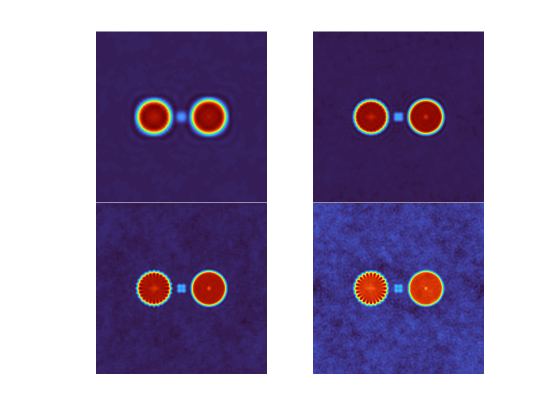

colormap Turbo
nexttile
imagesc(imgNoiseXT12p(:,:,1))
axis square
axis off
nexttile
imagesc(imgNoiseXT12p(:,:,2))
axis square
axis off
nexttile
imagesc(imgNoiseXT12p(:,:,3))
axis square
axis off
nexttile
imagesc(imgNoiseXT12p(:,:,4))
axis square
axis off

t.TileSpacing = 'none';

t=tiledlayout(2,4)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 4]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


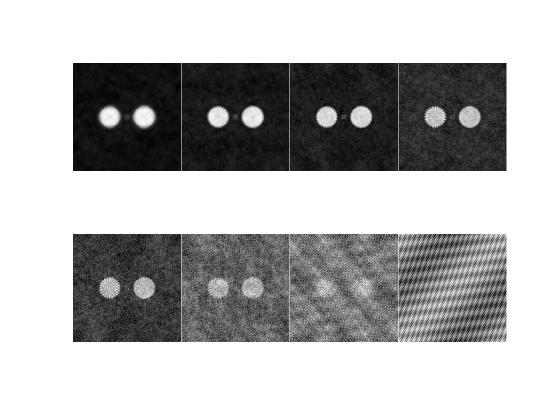

colormap gray
nexttile
imagesc(imgNoiseXT22p(:,:,1))
axis square
axis off
nexttile
imagesc(imgNoiseXT22p(:,:,2))
axis square
axis off
nexttile
imagesc(imgNoiseXT22p(:,:,3))
axis square
axis off
nexttile
imagesc(imgNoiseXT22p(:,:,4))
axis square
axis off
nexttile
imagesc(imgNoiseXT22p(:,:,5))
axis square
axis off
nexttile
imagesc(imgNoiseXT22p(:,:,6))
axis square
axis off
nexttile
imagesc(imgNoiseXT22p(:,:,7))
axis square
axis off
nexttile
imagesc(imgNoiseXT22p(:,:,8))
axis square
axis off
t.TileSpacing = 'none';

OTFs

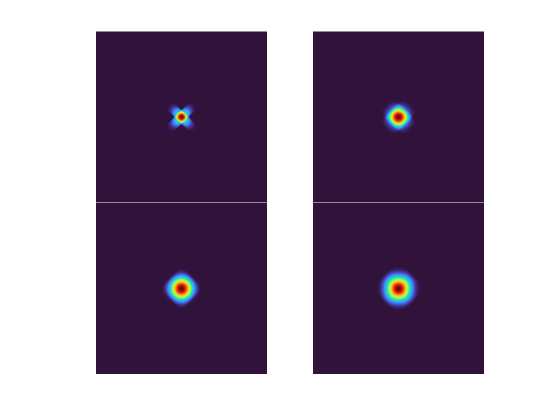

tiledlayout(2,2,'TileSpacing',"none");
colormap Turbo
nexttile
imagesc(OTFXT12p(:,:,1))
axis square
axis off
nexttile
imagesc(OTFXT12p(:,:,2))
axis square
axis off
nexttile
imagesc(OTFXT12p(:,:,3))
axis square
axis off
nexttile
imagesc(OTFXT12p(:,:,4))
axis square
axis off

t=tiledlayout(2,4)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 4]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


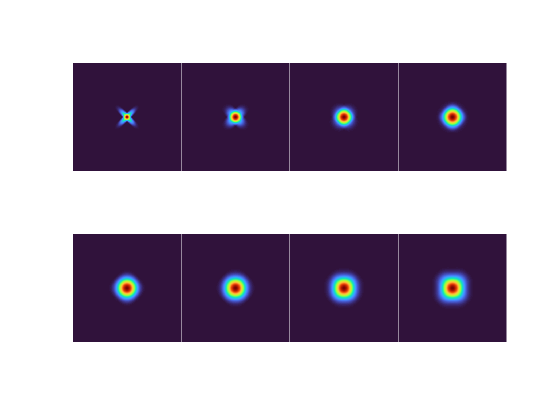

colormap Turbo
nexttile
imagesc(OTFXT22p(:,:,1))
axis square
axis off
nexttile
imagesc(OTFXT22p(:,:,2))
axis square
axis off
nexttile
imagesc(OTFXT22p(:,:,3))
axis square
axis off
nexttile
imagesc(OTFXT22p(:,:,4))
axis square
axis off
nexttile
imagesc(OTFXT22p(:,:,5))
axis square
axis off
nexttile
imagesc(OTFXT22p(:,:,6))
axis square
axis off
nexttile
imagesc(OTFXT22p(:,:,7))
axis square
axis off
nexttile
imagesc(OTFXT22p(:,:,8))
axis square
axis off
t.TileSpacing = 'none';

Generate PSFs

for ii=1:8
    PSFXT22p(:,:,ii)=abs(ifftshift(ifft2(ifftshift(OTFXT22p(:,:,ii)))));
end
for ii=1:8
    PSFXT22pN(:,:,ii)=Norm(PSFXT22p(:,:,ii));
end

for ii=1:4
    PSFXT12p(:,:,ii)=abs(ifftshift(ifft2(ifftshift(OTFXT12p(:,:,ii)))));
end
for ii=1:4
    PSFXT12pN(:,:,ii)=Norm(PSFXT12p(:,:,ii));
end


## Reconstructions

% XT22p with noise

PSFS=PSFXT22pN(:,:,1:7);
Images=imgNoiseXT22p(:,:,1:7);

s=size(PSFS);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSFS,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(Images,[s(1) s(1)*s(3)]);
%bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
bdn=conv_fft2(Imdata,delta);
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=1000;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 1487.779293 seconds.


clear recMPIMN3XT errorrecrecMPIMN3XT
recMPIMN3XT=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0410

for ii=1:size(recMPIMN3XT,3)
    errorrecrecMPIMN3XT(ii)=immse(Norm(trueimage),Norm(recMPIMN3XT(:,:,ii)));
end

[evalXT locmXT]=min(errorrecrecMPIMN3XT);
evalXT

evalXT = 0.0075

locmXT

locmXT = 401

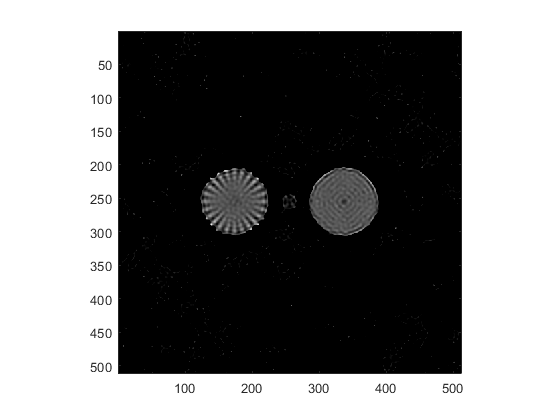

figure; imagesc(recMPIMN3XT(:,:,locmXT))
axis square
colormap gray

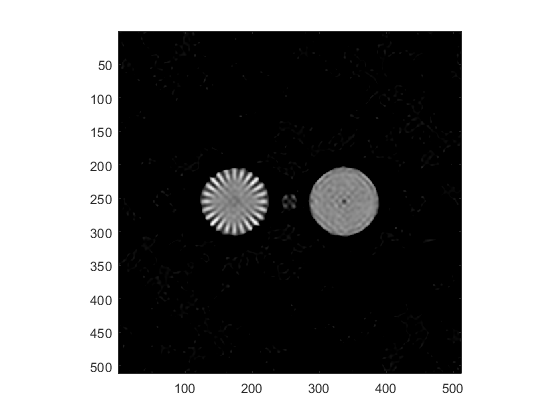

figure; imagesc(recMPIMN3XT(:,:,locmXT-320))
axis square
colormap gray